T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;

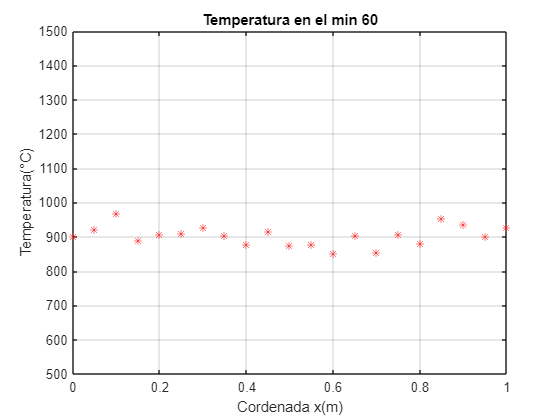

for i = 1:n
    plot(x,T(i,:),'r*')
    title(sprintf('Temperatura en el min %d',i-1))
    xlabel('Cordenada x(m)')
    ylabel('Temperatura(°C)')
    grid on
    ylim([500 1500])
    pause(1 -0.6)
end

clf
for i = 1:n
    TemperaturaPromedio = promedio(T(i,:));
    hold on
    plot(i,TemperaturaPromedio,'bo')
    hold off
end
surf(T)